% Model Initialization
% Simple Track

## Add images to the path

addpath(genpath('Images'));

## Load scene data files

load data from Driving Scenario Designer

load('scenario1.mat');
refPose = data_scenario1.data.ActorSpecifications(1,1).Waypoints;

## Define reference points

xRef = refPose(:,1);
yRef = refPose(:,2);

## Define vehicle parameters 

X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

## Calculating reference pose vectors

**Based on how far the vehicle travels, the pose is generated using 1-D lookup tables.**

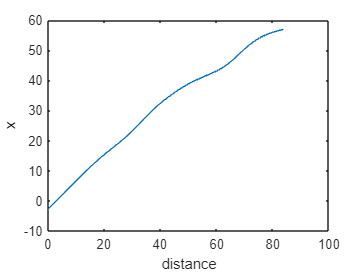

% calculate distance vector
distancematrix = squareform(pdist(refPose));
distancesteps = zeros(length(refPose)-1,1);
for i = 2:length(refPose)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,50); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
yRef2s = smooth(gradbp,yRef2); % smooth waypoints
xRef2s = smooth(gradbp,xRef2); % smooth waypoints
plot(gradbp,xRef2s)
xlabel('distance')
ylabel('x')

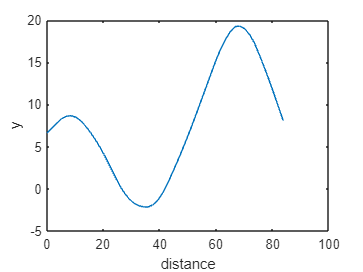

plot(gradbp,yRef2s)
xlabel('distance')
ylabel('y')

## Calculate theta vector

**theta = orientation angle of the path at reference points **

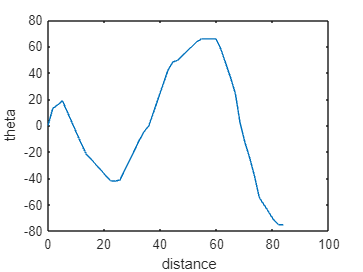

thetaRef = zeros(length(gradbp),1);
for i = 2:length(gradbp)
    thetaRef(i,1) = atan2d((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
end
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta
psi_o = thetaRefs(1)*(pi/180); % initial yaw angle
plot(gradbp,thetaRefs)
xlabel('distance')
ylabel('theta')

## Create direction vector

direction = ones(length(gradbp),1);


## Calculate curvature vector

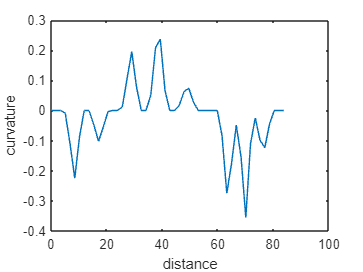

curvature = getCurvature(xRef2,yRef2);
plot(gradbp,curvature)
xlabel('distance')
ylabel('curvature')

## Curvature Function

function curvature = getCurvature(xRef,yRef)
% Calculate gradient by the gradient of the X and Y vectors
DX = gradient(xRef);
D2X = gradient(DX);
DY = gradient(yRef);
D2Y = gradient(DY);
curvature = (DX.*D2Y - DY.*D2X) ./(DX.^2+DY.^2).^(3/2);
end

*Copyright 2021 The MathWorks, Inc.*